# Titanic Dataset Predication Models

Here is an example code that helps you to go through each step of building and evaluating the decision tree model. Please be encouraged to try to think yourself first with the provided comments. Please make sure that the code has been understood in this example before moving on.

Data is imported as a table. Tables store data in column-orientd or tabular data. Table variables can have different data types and sizes as long as all varibles have the same number of rows. Table variables have names, just as the fields of a structure have names. Use the summary function to get information about a table

clear;
clc;
close all;

Now we will readt the data in.

titanicData = readtable("titanic_data.csv");
% summary(titamicData)

Now we will build the decision tree model.

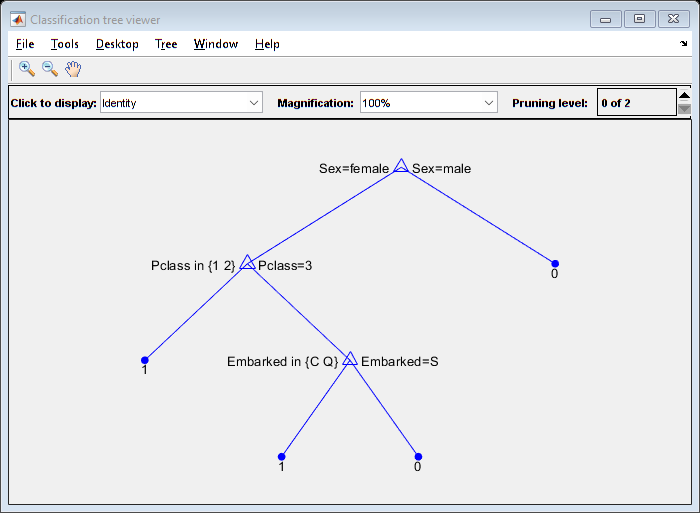

inputTable = titanicData;

% Change the Pclass from number to char (categorical variable) for
% convience 
inputTable.Pclass= num2str(inputTable.Pclass);

% ~~Predictors and Response~~
% This code processes the data into the correct shape for training the
% model
predictorNames = {'Pclass','Sex','Embarked'};
predictors = inputTable(:,predictorNames);  % Could also be predictorNames = inputTable(:,[3,5,12]);
response = inputTable.Survived;

% ~~Train the classifier~~
% This code specifies all the classifier options and trains the classifier
% option and trains the classifier
trainedDecisionTreeModel = fitctree(predictors,response);

% ~~Graphic respresentation of the tree~~
view(trainedDecisionTreeModel,'mode','graph')

% text description (rule generated by the tree)
view(trainedDecisionTreeModel) 

Decision tree for classification
1  if Sex=female then node 2 elseif Sex=male then node 3 else 0
2  if Pclass in {1 2} then node 4 elseif Pclass=3 then node 5 else 1
3  class = 0
4  class = 1
5  if Embarked in {C Q} then node 6 elseif Embarked=S then node 7 else 0
6  class = 1
7  class = 0




% ~~Model preformance and evaluation on the training dataset~~
% Predicted class of the training 
predicatedY = resubPredict(trainedDecisionTreeModel); 

% Compute the accuracy
valaidationAccuracy = 1 - loss(trainedDecisionTreeModel,predictors,response);

We can now use Train/Test to evaluate the models preformance

% Split the data randomly into train and test groups, on a 70%/30% split
% First, get the size of the data
[m,n] = size(inputTable);

% Generate a vector containing random permutation of the integers from 1 to
% n without repeating
idx = randperm(m);

% Set the split perfectage
splitPercentage = 0.70;
% m1 is the number of the training data
m1 = round(splitPercentage*m);
% Now split the data
trainingData = inputTable(idx(1:m1),:);
testData = inputTable(idx(m1+1:end),:);

We will now build a new tree on the training data set only

predictors = trainingData(:, predictorNames);
response = trainingData.Survived;
trainedDecisionModdel1 = fitctree(predictors,response);

% Compute the accuracy on the training data
validationAccuracy1 = 1 - loss(trainedDecisionModdel1,predictors,response);

And now we will preform an evaluation on the test data, by initially looking at the confusion matrix. A `confusion matric` is a performance measurement used in ML classification problems where the output can be two or more classes. It is a table with 4 different combinations of predicted and actual values. 

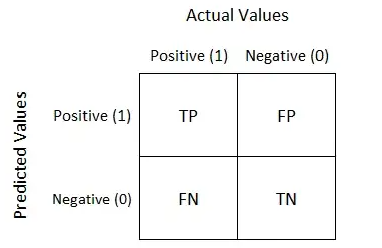

A `confusion matric` is useful for measuring Recall, Precision, Specificity Accuracy and ist importantly AUC-ROC curves.

If we use a pregnancy analogue:

**True Positive:**

- Interpretation: You predicted positive and it’s true.

- You predicted that a woman is pregnant and she actually is.

**True Negative:**

- Interpretation: You predicted negative and it’s true.

- You predicted that a man is not pregnant and he actually is not.

**False Positive: (Type 1 Error)**

- Interpretation: You predicted positive and it’s false.

- You predicted that a man is pregnant but he actually is not.

**False Negative: (Type 2 Error)**

- Interpretation: You predicted negative and it’s false.

- You predicted that a woman is not pregnant but she actually is.

Just remember: we describe predicted values as Positive and Negative and actual values as True and False.

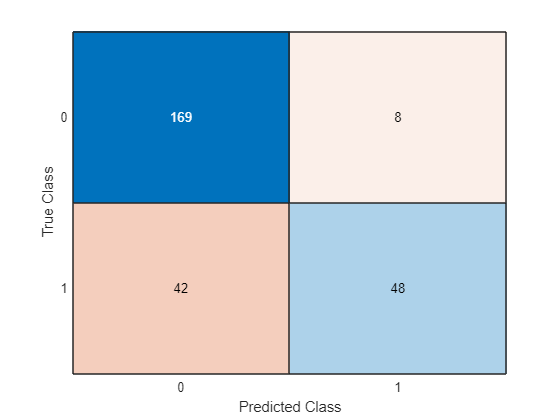

% Predict the labels of the test data
predictedY = predict(trainedDecisionModdel1,testData(:,predictorNames));

% Create a confusion matrix chart from the true labels and the predicted
% labelspredictedY
cm = confusionchart(testData.Survived,predictedY);

Provide a single test data which I will make up to use as a test

example_test=cell2table({504,0,'1','Laitinen, Miss. Kristina Sofia','male',37,0,0,4135,9.58750000000000,'','S'});

% Now to add in the correct variable headers
example_test.Properties.VariableNames = trainingData.Properties.VariableNames

example_test = 1×12 table
    PassengerId    Survived    Pclass                   Name                     Sex       Age    SibSp    Parch    Ticket     Fare       Cabin       Embarked
    ___________    ________    ______    __________________________________    ________    ___    _____    _____    ______    ______    __________    ________

        504           0        {'1'}     {'Laitinen, Miss. Kristina Sofia'}    {'male'}    37       0        0       4135     9.5875    {0×0 char}     {'S'}  


Prediction=predict(trainedDecisionTreeModel, example_test(1,:));
if Prediction==0
    disp('Your testing subject will not survive.');
else
    disp('Your testing subject will survive.');
end

Your testing subject will not survive.
